nx1 = 0 : 9;
nh1 = 0 : 4;

x = [ones(1, 5), zeros(1, 5)];
h1 = [1, -1, 3, 0, 1];
h2 = [0, 2, 5, 4, -1];

nw = nh1(1) + nx1(1) : nh1(end) + nx1(end);

w = conv(x, h1);

ny1 = nw(1) + nh1(1) : nw(end) + nh1(end);
yd1 = conv(w, h2)

yd1 =      0     2     5    10    20    35    35    36    30    20     5     3    -1     0     0     0     0     0


nh2 = nh1(1) + nh1(1) : nh1(end) + nh1(end);
hseries = conv(h1, h2);

ny2 = nx1(1) + nh2(1) : nx1(end) + nh2(end);
yd2 = conv(x, hseries);

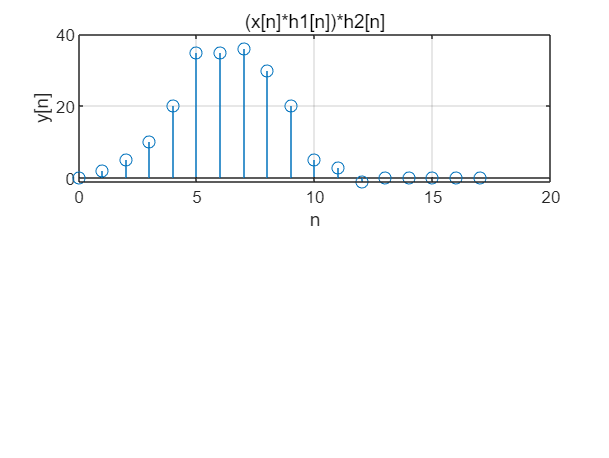

subplot(2, 1, 1);
stem(ny1, yd1);
title("(x[n]*h1[n])*h2[n]");
xlabel("n")
ylabel("y[n]");
grid on;

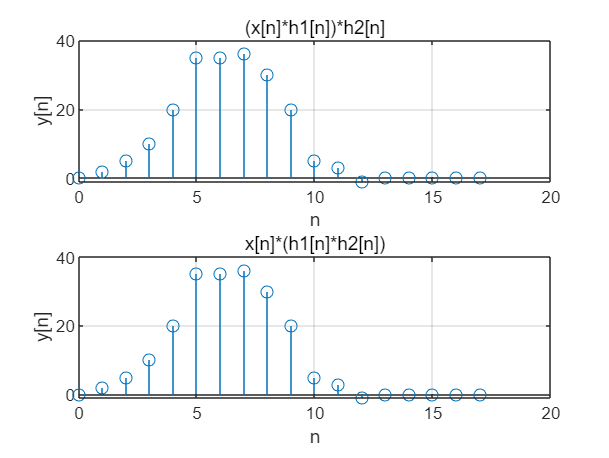

subplot(2, 1, 2);
stem(ny2, yd2);
title("x[n]*(h1[n]*h2[n])");
xlabel("n")
ylabel("y[n]");
grid on;